# BINOMIAL DISTRIBUTION (GRAPHICAL ANALYSIS): RELATION BETWEEN PROBABILITY OF SUCCESS (p) & FAILURE (q) WITH THE SKEWNESS 

## Binomial Distribution Function 

####                     
$$b\left(x\;;n\;,p\;\right)=C_x^n \;p^{x\;} q^{n-x} \;\;;\;\;\;\;x=0,1,2,3\ldotp \ldotp \ldotp$$


                                                        
$$\begin{array}{l}
n=\textrm{Total}\;\textrm{number}\;\textrm{of}\;\textrm{events}\\
x=\textrm{Total}\;\textrm{number}\;\textrm{of}\;\textrm{successfull}\;\textrm{events}\\
p=\textrm{Probability}\;\textrm{of}\;\textrm{success}\;\textrm{in}\;a\;\textrm{single}\;\textrm{trial}\;\\
q=\textrm{Probability}\;\textrm{of}\;\textrm{failure}
\end{array}$$


### Formulas & Concepts


$$\textrm{Moment}\;\textrm{about}\;\textrm{mean}$$
                         
$$\textrm{Skewness}$$


    
$$\begin{array}{l}
\mu_1 =\textrm{Mean}=\mu_1^{\prime } =n\;p\\
\mu_2 =\textrm{Variance}=n\;p\\
\mu_3 =n\;p\;q\;\left(q-p\right)
\end{array}$$
                    
$$\begin{array}{l}
\beta_{1\;} =0\;\;;\;\;\;\;\;\textrm{Symmetric}\;\textrm{Distribution}\;\\
\beta_{1\;} >0\;\;;\;\;\;\;\;\textrm{Positively}\;\textrm{Skewed}\;\;\\
\beta_{1\;} <0\;\;;\;\;\;\;\;\textrm{Negitively}\;\textrm{Skewed}
\end{array}$$


### Cases to Analyse the Skewness Variation

####     Case (1)

    (Probability of Success = Probability of Failure)     $p=q$

####     Case (2)

    (Probability of Success > Probability of Failure)     $p>q$            $\vdots \;q=1-p$

####     Case (3)

    (Probability of Success < Probability of Failure)     $p<q$

### Case (1)     $p=q$

A coin is tossed12 times. What is the probability of getting exactly 7 heads?

p = 0.5;
q = 1-p;
n = 12;
for k = 0:7
    com = nchoosek(n,k);
bin = com*p^k*q^(n-k);
X = [k, bin]
disp(X)
end

X = 	1.0e+-3 *

         0    0.2441


   1.0e-03 *

         0    0.2441



X =     1.0000    0.0029


    1.0000    0.0029



X =     2.0000    0.0161


    2.0000    0.0161



X =     3.0000    0.0537


    3.0000    0.0537



X =     4.0000    0.1208


    4.0000    0.1208



X =     5.0000    0.1934


    5.0000    0.1934



X =     6.0000    0.2256


    6.0000    0.2256



X =     7.0000    0.1934


    7.0000    0.1934



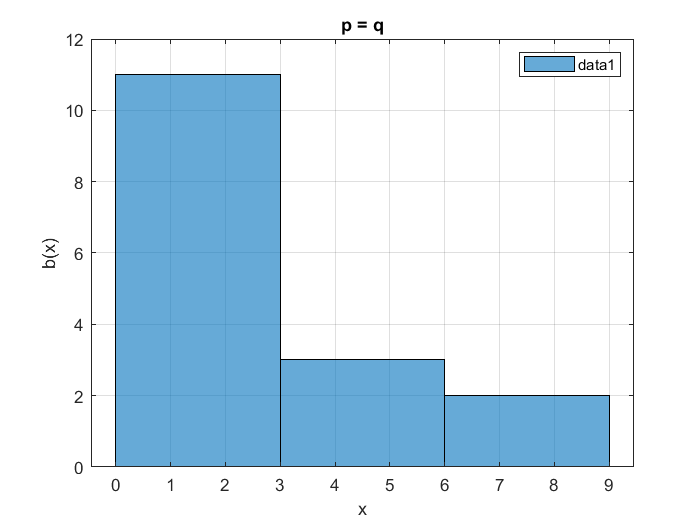


load ('c01.mat')
histogram(c01)

xlim([-0.45 9.45])
ylim([0.0 12.0])
grid on
legend('show')
title('p = q')
xlabel('x')
ylabel('b(x)')


mu = n*p

mu = 6.3000

var = n*p*q

var = 0.6300

std = sqrt(var)

std = 0.7937

#### Case (2)     $p>q$

On average, every one out of 10 telephones is found busy. Seven telephone numbers are selected at random. Find the probability that 5 of them will not found busy.


p = 0.9;
q = 1-p;
n = 7;
for k = 0:7
    com = nchoosek(n,k);
bin = com*p^k*q^(n-k);
X = [k, bin]
disp(X)
end

X = 	1.0e+-7 *

         0    1.0000


   1.0e-07 *

         0    1.0000



X =     1.0000    0.0000


    1.0000    0.0000



X =     2.0000    0.0002


    2.0000    0.0002



X =     3.0000    0.0026


    3.0000    0.0026



X =     4.0000    0.0230


    4.0000    0.0230



X =     5.0000    0.1240


    5.0000    0.1240



X =     6.0000    0.3720


    6.0000    0.3720



X =     7.0000    0.4783


    7.0000    0.4783




load ('c02.mat')
histogram(c02)

Unrecognized function or variable 'c02'.


xlim([-0.45 9.45])
ylim([0.0 12.0])
grid on
legend('show')
title('p > q')
xlabel('x')
ylabel('b(x)')


mu = n*p
var = n*p*q
std = sqrt(var)


#### Case (3) $\;\;\;\;\;\;p<q$

On average, every one out of 10 telephones is found busy. Six telephone numbers are selected at random. Find the probability that four of them will be busy.

p = 0.1;
q = 1-p;
n = 6;
for k = 0:6
    com = nchoosek(n,k);
bin = com*p^k*q^(n-k);
X = [k, bin]
disp(X)
end


load ('c03.mat')
histogram(c03)

xlim([-0.30 6.30])
ylim([0.00 10.00])
grid on
legend('show')
title('p<q')
xlabel('x')
ylabel('b(x)')



mu = n*p
var = n*p*q
std = sqrt(var)
